clc;
clear;

[x,t] = ovarian_dataset;
whos x t;

  Name        Size              Bytes  Class     Attributes

  t           2x216              3456  double              
  x         100x216            172800  double              



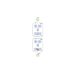

setdemorandstream(672880951);
net = patternnet(5);
view(net);

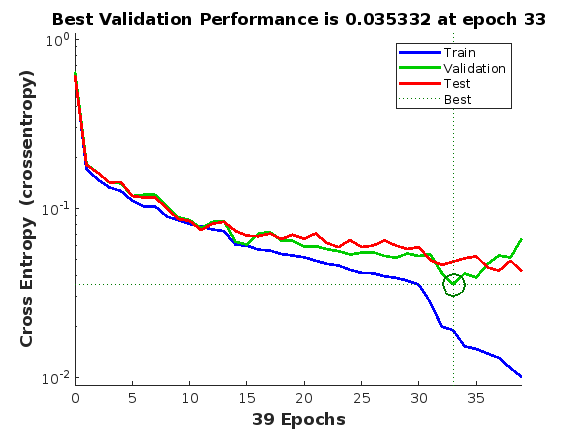

[net,tr] = train(net,x,t);
plotperform(tr);

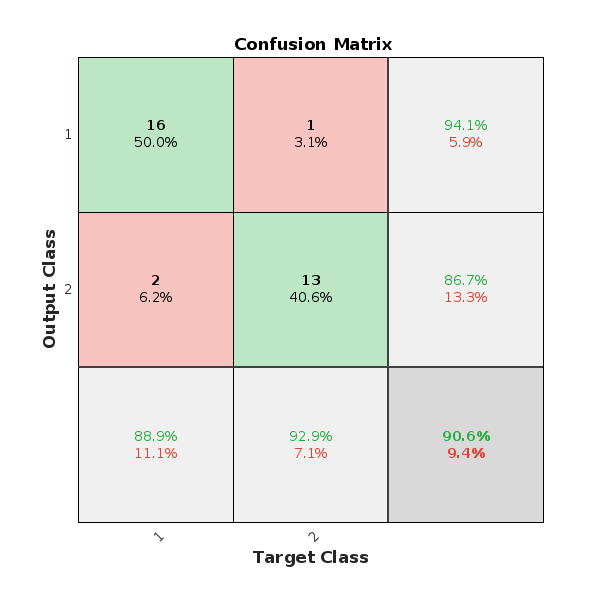

testX = x(:,tr.testInd);
testT = t(:,tr.testInd);


testY = net(testX);
testClasses = testY > 0.5;
plotconfusion(testT,testY);

[c,cm] = confusion(testT,testY);

fprintf('Percentage Correct Classification   : %f%%\n', 100*(1-c));

Percentage Correct Classification   : 90.625000%


fprintf('Percentage Incorrect Classification : %f%%\n', 100*c);

Percentage Incorrect Classification : 9.375000%


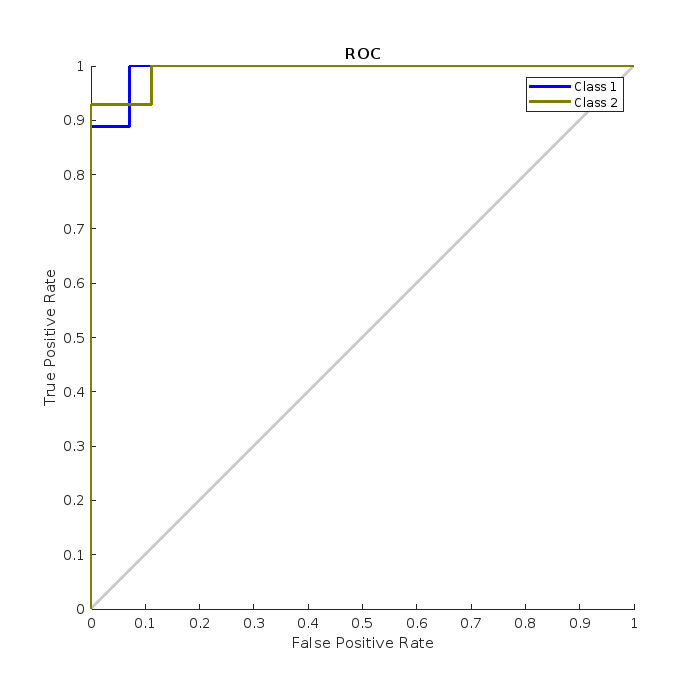

plotroc(testT,testY);